commonPath = "C:\Users\Ankith Mohan\Documents\GitHub\SEP\";
for folder = ["cvx-w64", "experiments", "helpers", "QETLAB", "SDPs"]
    addpath(genpath(commonPath + folder));
end

Reference

% executeExpt(dim_A, dim_B, K_se, K_bse, N_seeSaw, N_rand, N_ops, threshold, opt)
K_se = 1

K_se = 5

K_bse = 1

K_bse = 5

N_seeSaw = 100

N_seeSaw = 100

N_rand = 100

N_rand = 100

N_summand = 10

N_summand = 10

N_ops = 100

N_ops = 100

threshold = 1e-3

threshold = 1.0000e-03

% Upper bounds: "PPT", "realignment", "SymExt", "BosSymExt"
% Square root: "sqrt_simple_A", "sqrt_simple_B", 
%              "sqrt_rev_1_A", "sqrt_rev_1_B", 
%              "sqrt_rev_2_A", "sqrt_rev_2_B" 
% Lower bounds: "MM_simple", "MM_rev_1", "MM_rev_2", 
%               "US_simple", "US_rev_1", "US_rev_2", 
%               "rand_simple", "rand_rev_1", "rand_rev_2"
% dont_do = ["PPT", "realignment", "SymExt", "BosSymExt", ...
%            "sqrt_simple_A", "sqrt_simple_B", ...
%            "sqrt_rev_1_A", "sqrt_rev_1_B", ...
%            "sqrt_rev_2_A", "sqrt_rev_2_B", ...
%            "MM_simple", "MM_rev_1", ...
%            "US_simple", "US_rev_1", ...
%            "rand_simple", "rand_rev_1", "rand_rev_2"];

Herm experiments (sum)

dont_do = []


dont_do =

     []



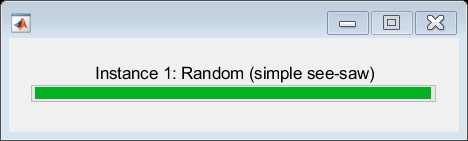

Output argument "sigma_A_rand_best" (and maybe others) not assigned during call to "computegamma_rand_sum".

Error in setupExpt (line 794)
                    gamma_rand_stop(n)] = computegamma_rand_sum(K_list, ...

Error in executeExpt (line 19)
            setupExpt(dim_A, dim_B, K_se, K_bse, N_seeSaw, N_rand, sum, ...

%for d = 2:10
d = 9
    executeExpt(d, d, K_se, K_bse, N_seeSaw, N_rand, 1, N_summand, N_ops, threshold, "Herm", 0, dont_do, 0)
    fprintf("Herm: Local dimension: %d executed successfully!\n", d);
%end

PSD experiments (not projection operator)

for d = [200, 300, 400, 500, 600, 700, 800, 900, 1000]
    executeExpt(d, d, K_se, K_bse, N_seeSaw, N_rand, 0, N_summand, N_ops, threshold, "Pos", 0, dont_do)
    fprintf("Pos: d = %d executed successfully!\n", d);
end

PSD experiments with projection operator

for d = d_Pos_start:d_Pos_finish
    executeExpt(d, d, K_se, K_bse, N_seeSaw, N_rand, 0, N_summand, N_ops, threshold, "Pos", 1, dont_do)
    fprintf("Pos: d = %d executed successfully!\n", d);
end

Herm experiments with projection operator

for d = d_Herm_start:d_Herm_finish
    executeExpt(d, d, K_se, K_bse, N_seeSaw, N_rand, 0, N_summand, N_ops, threshold, "Herm", 1, dont_do)
    fprintf("Herm: d = %d executed successfully!\n", d);
end